## Asse y - Live script di prova 

Dati

clc
close all
clear

Jm=0.074*10^(-3);   % [kg*m^2]
Jp1=1.2135*10^(-4); % [kg*m^2]
Jp2=6.5420*10^(-4); % [kg*m^2]
Jp3=0.5990*10^(-4); % [kg*m^2]

l5=683*10^(-3)/2; % [m] lunghezza albero riferita alla metà di albero da un lato e basta
d5=19*10^(-3); % [m]; diametro albero
rho=7850; %[kg/m^3] acciaio
J5=1/2*(pi*(d5/2)^2*l5*rho)*(d5/2)^2;
nu = 0.3;
E = 206000*10^6 ; % [N/m^2]
Jt5 = (pi / 32) * d5^4 ; % [m^4]
G=E/(2*(nu+1));
k5 = G* Jt5 / l5;
Mx=12; %[kg]

kcs1=1.900*10^7; % [N/m] rig. cinghia tratto 1 specifica ( da moltiplicare per spessore e dividere per lunghezza)
w1=25*10^(-3); % [m] spessore cinghia 1 tratto
kcs2=2.340*10^7; % [N/m] 
w2=15*10^(-3); % [m] spessore cinghia 2 tratto

d1=23.87*10^(-3); % [m] diametro puleggia 1
d2=76.39*10^(-3); % [m] diametro puleggia 2
d3=31.83*10^(-3); % [m] diametro puleggia 3
r1=d1/2 ; r2=d2/2; r3=d3/2;
a1=119*10^(-3); % [m] ; %interasse primo tratto
a2=1036*10^(-3); % [m]; %interasse secondo tratto

Cm=0.45;

Calcolo lunghezze tratti di cinghia

%l1_tot=pi*(r1+r1)+2*sqrt(a1^2+(r1-r2)^2); %lunghessa dell'anello di cinghia
%theta=(r2-r1)/a1;
%l1=(r2-r1)/tan(theta); %tratto chiuso del motore

l1_tot=(2*a1)+(pi/2)*(d1+d2)+((d1-d2)^2)/(4*a1);
l1_intermedio=l1_tot-pi*(r1+r2);
l1=l1_intermedio/2

l1 = 0.1219


%l2_tot=2*pi*r3+2*a2;
%l2=(l2_tot-2*pi*r3)/2; %tratto in zona carrello

l2_tot=(2*a2)+(pi/2)*(d3+d3)+((d3-d3)^2)/(4*a2);
l2_intermedio=l2_tot-pi*(r3+r3);
l2=l2_intermedio/2

l2 = 1.0360


k1=kcs1*w1/l1; k2=kcs2*2*w2/(l2); k3=k2; k4=kcs2*w2/l2;

Calcolo matrici M, D, K

disp('matrice delle masse')

matrice delle masse



M = [Jm+Jp1, 0     , 0  , 0  , 0;
        0, 2*J5+Jp2, 0  , 0  , 0;
        0,    0  , 2*Jp3, 0  , 0;
        0,    0  ,   0, 2*Jp3, 0;
        0,    0  ,   0,   0  , Mx]

M =     0.0002         0         0         0         0
         0    0.0007         0         0         0
         0         0    0.0001         0         0
         0         0         0    0.0001         0
         0         0         0         0   12.0000



disp('matrice delle rigidezze')

matrice delle rigidezze


K=[2*k1*(r1^2),    -2*k1*r2*r1,        0    ,           0                        , 0;
   -2*k1*r1*r2,  (2*k1*r2^2)+2*k5,   -2*k5    ,           0                    , 0;
      0     ,         -2*k5    ,        (2*k5)+(k2+k4)*r3^2, -(r3^2)*k4               , -2*r3*k2;
      0     ,        0 ,         -2*k4*r3^2,     2*(k3+k4)*r3^2 , -2*r3*k3;
      0     ,         0    ,         -2*r3*k2,        -2*k3*r3,                  2*(k2+k3)]

K = 	1.0e+06 *

    0.0011   -0.0036         0         0         0
   -0.0036    0.0173   -0.0059         0         0
         0   -0.0059    0.0062   -0.0001   -0.0216
         0         0   -0.0002    0.0005   -0.0216
         0         0   -0.0216   -0.0216    2.7104



% disp('matrice degli smorzamenti')
C=zeros(5,5)% % 

C =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


% % C=[0, 0 , 0, 0 , 0;
% %    0, 0 , 0, 0 , 0;
% %    0, 0 , 0, 0 , 0;
% %    0, 0 , 0, 0 , 0;
% %    0, 0 , 0, 0 , 0]
F = [Cm;0;0;0;0] %forcing force on the 4rd coordinate

F =     0.4500
         0
         0
         0
         0


**Calcolo autovalori e autovettori**

(Modi di vibrare e pulsazioni caratteristiche)

%disp('V contiene gli autovettori, "D" contiene gli autovalori su diagonale')
%[v,d]=eig(inv(M)*K);
% the eigenvalues are the nat. freq. at the power of 2
%disp('Matrice v, ogni colonna equivale ad un autovettore: ')
%disp(v);
%disp('Matrice d, matrice diagonale contente gli autovalori: ')
%disp(d);
[V, D]=show_mode(M,K)

mode 1 - natural frequency w = 0.000000 [rad/s] - 0.000000 [Hz] 
A1 = 1.000000 
A2 = 0.314354 
A3 = 0.319259 
A4 = 0.276805 
A5 = 0.004120 
mode 2 - natural frequency w = 499.184849 [rad/s] - 79.447736 [Hz] 
A1 = -1.000000 
A2 = -0.298774 
A3 = -0.263469 
A4 = 0.182909 
A5 = 0.006210 
mode 3 - natural frequency w = 2088.225709 [rad/s] - 332.351444 [Hz] 
A1 = -0.026852 
A2 = -0.001952 
A3 = 0.011415 
A4 = 1.000000 
A5 = -0.000440 
mode 4 - natural frequency w = 4312.804431 [rad/s] - 686.404144 [Hz] 
A1 = 0.942961 
A2 = -0.669773 
A3 = -1.000000 
A4 = 0.099058 
A5 = 0.000088 
mode 5 - natural frequency w = 7916.962315 [rad/s] - 1260.023687 [Hz] 
A1 = -0.070515 
A2 = 0.220994 
A3 = -1.000000 
A4 = 0.024453 
A5 = 0.000028 


V =     0.8848   -0.9159   -0.0268    0.6154   -0.0687
    0.2781   -0.2736   -0.0020   -0.4371    0.2152
    0.2825   -0.2413    0.0114   -0.6527   -0.9739
    0.2449    0.1675    0.9996    0.0647    0.0238
    0.0036    0.0057   -0.0004    0.0001    0.0000


D = 	1.0e+07 *

   -0.0034         0         0         0         0
         0    0.0249         0         0         0
         0         0    0.4361         0         0
         0         0         0    1.8600         0
         0         0         0         0    6.2678



w_max=sqrt(max(max(D))) % [rad/s] massima wn

w_max = 7.9170e+03

## Metodo di normalizzazione rispetto alla matrice delle masse M

%pii=zeros(5,1);
%pii_quadro=zeros(5,1);
%W_i= zeros(5,1);
%for ti=1:5
%    
%    pii_quadro(ti,1)=(v(:,ti)'*M*v(:,ti))\1;
%    pii(ti,1)=sqrt(pii_quadro(ti,1));
 %   W_i(ti,1)=sqrt(d(ti,ti));
%end %adesso ho lo scalare pi che rende unitaria la rispettiva massa modale
%K_norm=zeros(5,5);
%M_norm=zeros(5,5);
%mi interessano solo gli ele
%for ti=1:5
%    M_norm(ti,ti)=pii(ti)*v(:,ti)'*M*pii(ti)*v(:,ti);       %rigidezza_modale(ti,ti)=v(:,ti)'*K*v(:,ti);  %M_norm(ti,ti)= massa_modale(ti,ti)/pii(ti)^2; %K_norm(ti,ti)=rigidezza_modale(ti,ti)/M_norm(ti,ti);
%    K_norm(ti,ti)= d(ti,ti);
%end

## ipotesi di smorzamento proporzionale, quindi vale la relazione:

fi'*C*fi= a*(massa_modale)+b(rigidezza_modale)= smorzamento_modale

dove      per i=j  ---> ci= 2*smorzamento*pulsazione_i

              per i!=j ---> ci=0

definizione coeffieciente di smorzamento

z=0.7

z = 0.7000

%C_mx=zeros(5,5);

%for ti=1:5    %C_mx(ti,ti)= 2*massa_modale(ti,ti)*z_smorzamento*W_i(ti,1);
%    C_mx(ti,ti)= 2*z*W_i(ti,1);
%end

%M_norm,K_norm,C_mx
%C_0=v*C_mx*v'
%F_modale = v'*F;

## medoto di normalizzazione della componente unitaria 

%V_n= zeros(5,5);
%for ti=1:5
%    fscala = max(abs(v(:,ti)));
%    for jj=1:5
%       V_n(jj,ti)=v(jj,ti)/fscala;  
%    end
%end
%V_n

massa_modale=zeros(5,5);
rigidezza_modale=zeros(5,5);
C_mx1=zeros(5,5);

for ti=1:5
    massa_modale(ti,ti) = V(:,ti)'*M*V(:,ti);
    rigidezza_modale(ti,ti) = V(:,ti)'*K*V(:,ti);
end

rigidezza_modale,massa_modale

rigidezza_modale = 	1.0e+03 *

   -0.0132         0         0         0         0
         0    0.1536         0         0         0
         0         0    0.5328         0         0
         0         0         0    4.9045         0
         0         0         0         0    9.2823


massa_modale = 	1.0e+-3 *

    0.3851         0         0         0         0
         0    0.6165         0         0         0
         0         0    0.1222         0         0
         0         0         0    0.2637         0
         0         0         0         0    0.1481



for ti=1:5
    C_mx1(ti,ti)=2*z*sqrt(massa_modale(ti,ti)*rigidezza_modale(ti,ti));
end
C_mx1

C_mx1 =    0.0000 + 0.0996i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.4308 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.3572 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.5921 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.6414 + 0.0000i



C_1=((V')^-1)*C_mx1*((V)^-1);
F_modale1 = V'*F;


## Confronto della matrici C ricavate dai due metodi:

%disp('C dalla normalizzazione della massa:')
%C_0
disp('C dalla normalizzazione degli autovettori:')

C dalla normalizzazione degli autovettori:


C_1

C_1 = 	1.0e+03 *

   0.0004 + 0.0000i  -0.0010 + 0.0000i  -0.0001 + 0.0000i  -0.0000 + 0.0000i  -0.0112 + 0.0050i
  -0.0010 + 0.0000i   0.0042 + 0.0000i  -0.0008 + 0.0000i  -0.0000 + 0.0000i  -0.0168 + 0.0058i
  -0.0001 + 0.0000i  -0.0008 + 0.0000i   0.0012 + 0.0000i  -0.0000 + 0.0000i  -0.0069 + 0.0010i
  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0003 + 0.0000i  -0.0135 + 0.0006i
  -0.0112 + 0.0050i  -0.0168 + 0.0058i  -0.0069 + 0.0010i  -0.0135 + 0.0006i   5.4354 + 1.1077i


## Tracciamento dei grafici:


$$\left(
-\Omega^2M + 1j\Omega C +K
\right)
X = F$$



%thehta1,theta2,theta3,theta4,x,
x0=[0; 0; 0;0 ; l2/2] %inital condition on position

x0 =          0
         0
         0
         0
    0.5180


dotx0=[0; 0; 0; 0 ;0]; %initial condition con speed
%evaluation of the coeffcient of the linear comb. of modes
coeff=coeff_free_vib(V,D,x0,dotx0);
disp('coefficients of the linear combination')

coefficients of the linear combination


disp(coeff)

         0
   54.6188
         0
   54.3037
         0
  -22.6038
         0
    1.4328
         0
    1.1623



disp('time response of the two coordinates')

time response of the two coordinates



%vector with the frequencies at wich evaluete the solutions (200 solutions)
wmax= 8000;
Om=-0:(2*wmax)/200:2*wmax;

%solves and plots the amplitude of vibrations of the coordinates
disp('C nulla   ')

C nulla   


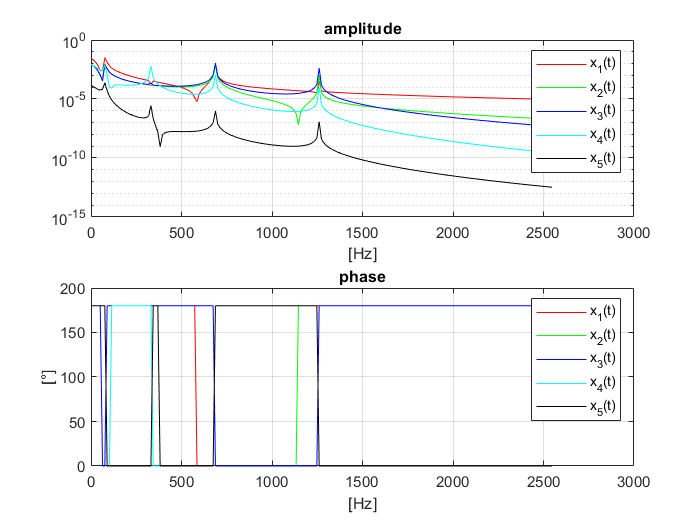

plotForcedDumped(M,C,K,F,Om)

%disp('Grafici con C ricavata dalla normalizzazione della masse:')
%plotForcedDumped(M,C_0,K,F,Om)
disp('Grafici con C ricavata dalla normalizzazione degli autovettori:')

Grafici con C ricavata dalla normalizzazione degli autovettori:


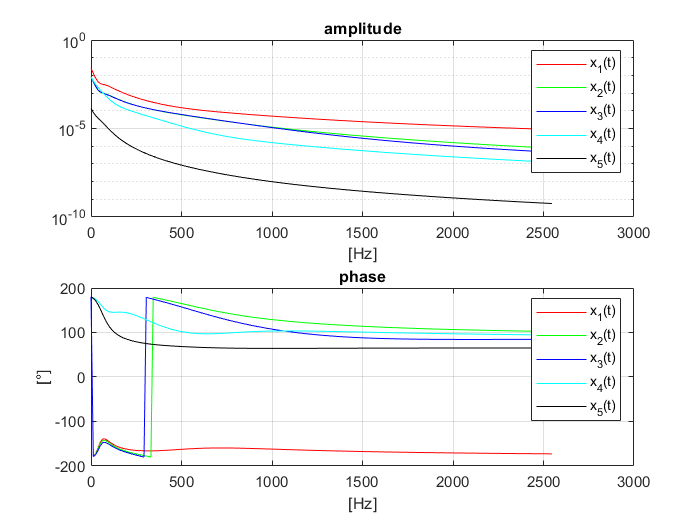

plotForcedDumped(M,C_1,K,F,Om)

## return 

## Vibrazioni libere


return
%column vectors
x0=[0; 0; 0; 0 ; l2/4] %inital condition on position
dotx0=[0; 0; 0; 0; 0]; %initial condition con speed
%evaluation of the coeffcient of the linear comb. of modes
coeff=coeff_free_vib(v,d,x0,dotx0);
disp('coefficients of the linear combination')
disp(coeff)

disp('time response of the two coordinates')
plot_free_vib(v,d,coeff);


sistema Forzato


$$\left(
-\Omega^2M + 1j\Omega C +K
\right)
X = F$$


  F = [1; 0;0;0;0] ;%forcing force 

Mnorm = inv(V).*M.*V;
Knorm = inv(V).*K.*V;

xi=0.1;
Cnorm=2*xi.*Mnorm.*sqrt(D)
C=V.*Cnorm.*inv(V)

%vector with the frequencies at wich evaluete the solutions (200 solutions)
Om=1*2*pi:(2*w_max)/200:2*w_max;

%solves and plots the amplitude of vibrations of the coordinates

plotForcedDumped(M,C,K,F,Om)
plotForcedDumped(Mnorm,Cnorm,Knorm,F,Om)